# Tutorial Notebook for KAMEL-LOBE

#### S. Arman Ghaffarizadeh & Gerald J. Wang

#### Companion notebook for "Getting over the Hump with KAMEL-LOBE: Kernel-Averaging Method to Eliminate Length-Of-Bin Effects in Radial Distribution Functions" in *Journal of Chemical Physics* (2023) 

This notebook is for building intuition and familiarity with the KAMEL-LOBE method; to perform KAMEL-LOBE on an existing RDF, please use the function in KAMEL_LOBE.m.

## Loading sample radial distribution functions 

We first load two sample RDFs. Both were obtained from the exact same underlying simulation, with the only difference being two different choices for the length of bin (`delr`). We also define the system number density (`Density`).

% load sample RDFs
NumData = 2;
for i=1:NumData
    FileName = sprintf('RDF_Sample_%d.txt',i);
    RDF{i} = readmatrix(FileName); % each cell entry contains an RDF with information for r and g(r)
    Nbin(i,1) = size(RDF{i},1); % total number of bins
    delr(i,1) = RDF{i}(3,1)-RDF{i}(2,1); % length of bin
end

% system information 
TotParticles = 2000; % total number of particles in the box
Lbox = 12; % box side length
Density = TotParticles/Lbox^3;  % number density of the system 


## Plotting raw RDF profiles

We now plot the two sample RDFs. It is clear to see the effect of the first sample RDF using more bins than the second sample RDF.

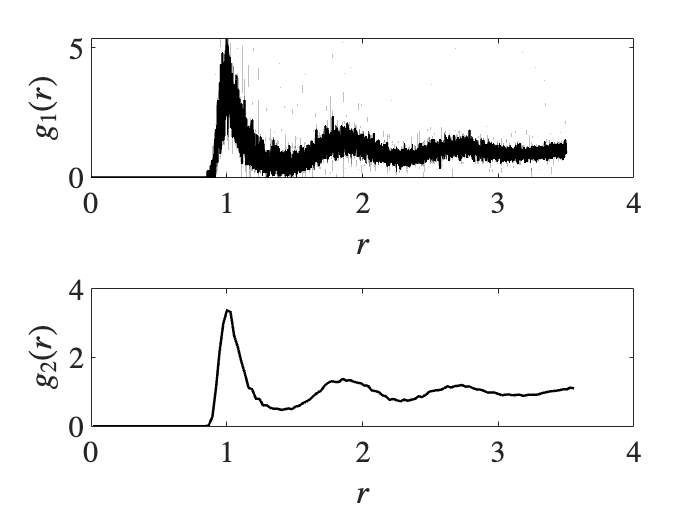


close all
for i=1:NumData
    subplot(2,1,i)
    plot(RDF{i}(:,1),RDF{i}(:,2),'k','LineWidth',2)
    xlabel('$r$','Interpreter','latex');
    ylabel_name = sprintf('$g_%d(r)$',i);
    ylabel(ylabel_name,'Interpreter','latex');
    set(gca,'FontSize', 24);
    set(gca,'fontname','times')
end

## **KAMEL-LOBE**

Here, we begin the 3-step process to obtain $ $\mathbf{\tilde g}=\mathbf{\mathbb T_3}\mathbf{\mathbb T_2}\mathbf{\mathbb T_1}\bf g$$ 

### Step 1: Integrating $g(r)$ to obtain $N(r)$ [Eq. (2) of manuscript]

$\mathbf{\mathbb T_1}$ performs (trapezoidal-rule) integration: 

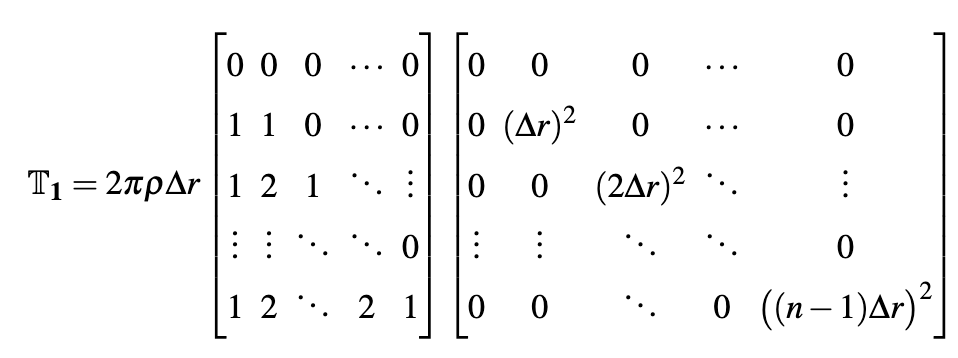

for i=1:NumData
    M1 = eye(Nbin(i,1)) + tril(2*ones(Nbin(i,1)),-1);
    M1(:,1) = 1;
    M1(1,:) = 0;
    M2 = diag((0:Nbin(i,1)-1).^2).*delr(i,1).^2;
    T1{i} = 2.*pi.*Density.*delr(i,1).*M1*M2;
end

for i=1:NumData
    Nr_raw{i} = T1{i}*RDF{i}(:,2);
end

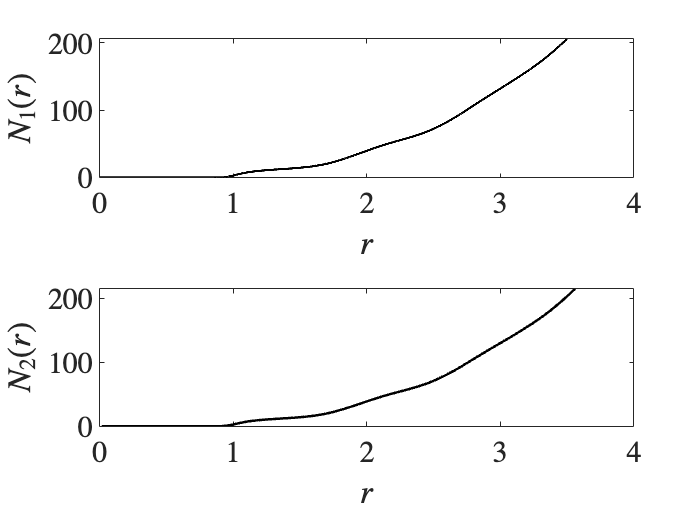

% plot N(r) 
close all
for i=1:NumData 
    subplot(NumData,1,i)
    plot(RDF{i}(:,1),Nr_raw{i}','k','LineWidth',2)
    xlabel('$r$','Interpreter','latex');
    ylabel_name = sprintf('$N_%d(r)$',i);
    ylabel(ylabel_name,'Interpreter','latex');
    set(gca,'FontSize', 24);
    set(gca,'fontname','times')
end

### Step 2: Smoothing $N(r)$ to obtain $\tilde N(r)$ [Eqs. (3)-(6) of manuscript]

Here, we construct the $\mathbf{\mathbb T_2}$ matrix for a Gaussian kernel as:

w = 0.015; % width of the Gaussian kernel

for i=1:NumData  
    m_KL = ceil(2*w/delr(i,1));
    T2_i = eye(Nbin(i,1),Nbin(i,1));
    A1_block = eye(m_KL);
    A2_block = zeros(m_KL,Nbin(i,1)-m_KL);
    B_block = T2_i(m_KL+1:end-m_KL,:);
    C1_block = A2_block;
    C2_block = A1_block;
    
    u_KL = zeros(1,2*m_KL-1);
    if m_KL >= 2
            u_KL(1,m_KL:end) = normcdf(((0:m_KL-1)+0.5)*delr(i,1),0,w)-normcdf(((0:m_KL-1)-0.5)*delr(i,1),0,w); 
            u_KL(1,1:m_KL-1) = flip(u_KL(1,m_KL+1:2*m_KL-1));
            u_KL = u_KL*(1/sum(u_KL));   
            B_block = spdiags(repmat(u_KL,Nbin(i,1)-2*m_KL,1),0:2*(m_KL-1), Nbin(i,1)-2*m_KL, Nbin(i,1));
    end
    T2_i = [A1_block A2_block;B_block;C1_block C2_block];
    T2{i} = full(T2_i); 
end

for i=1:NumData
    Nr_convert{i} = T2{i}*Nr_raw{i};
end

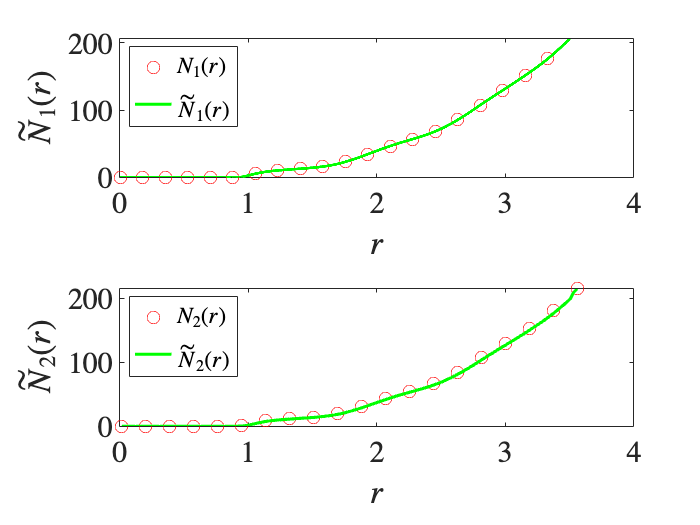

% plotting the converted N(r)
close all
close all
for i=1:NumData
    subplot(NumData,1,i);
    plot(RDF{i}(1:ceil(0.05*Nbin(i,1)):end,1),Nr_raw{i}(1:ceil(0.05*Nbin(i,1)):end,1),'ro','MarkerSize',10)
    hold on
    plot(RDF{i}(:,1),Nr_convert{i},'g-','LineWidth',2.5)  
    ylabel_name = sprintf('$\\tilde N_%d(r)$',i);
    ylabel(ylabel_name,'Interpreter','latex');
    set(gca,'FontSize', 24);
    set(gca,'fontname','times')
    xlabel('$r$','Interpreter','latex');
    [~, objh] = legend({sprintf('$N_%d(r)$',i),sprintf('$\\tilde N_%d(r)$',i)}, 'location', 'NorthWest', 'Fontsize', 18,'Interpreter','latex');
    objhl = findobj(objh, 'type', 'patch'); 
    set(objhl, 'Markersize', 12); 

end

### Step 3: Converting $\tilde N(r)$ to $\tilde g(r)$ [Eqs. (7)-(8) of manuscript]

We numerically compute the smoothed RDF via a centered-difference approximation:

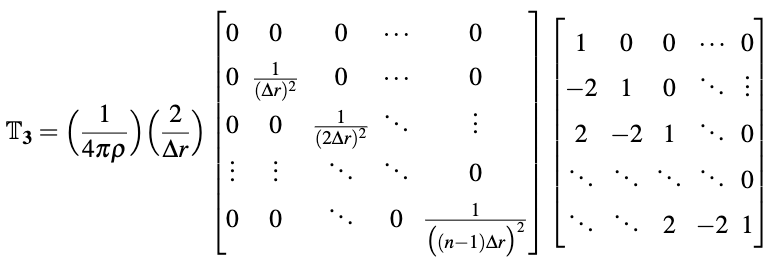

for i=1:NumData
    sq_r = zeros(Nbin(i,1),1);
    sq_r(2:end,1) = ((1:Nbin(i,1)-1).*delr(i,1)).^-2;
    r_exploded_out = repmat(sq_r,[1 Nbin(i,1)]);
    K = (-1).^((1:Nbin(i,1))+1) ;
    Ksq = K'*K;
    KTr = 2.*tril(Ksq);
    KTr(1:1+size(KTr,1):end) = 1;
    Kdiff = (2/delr(i,1)).*KTr;
    T3{i} = (1/(4.*pi.*Density)).*r_exploded_out.*Kdiff;
end

for i=1:NumData    
    gr_convert{i} = T3{i}*Nr_convert{i}; 
end

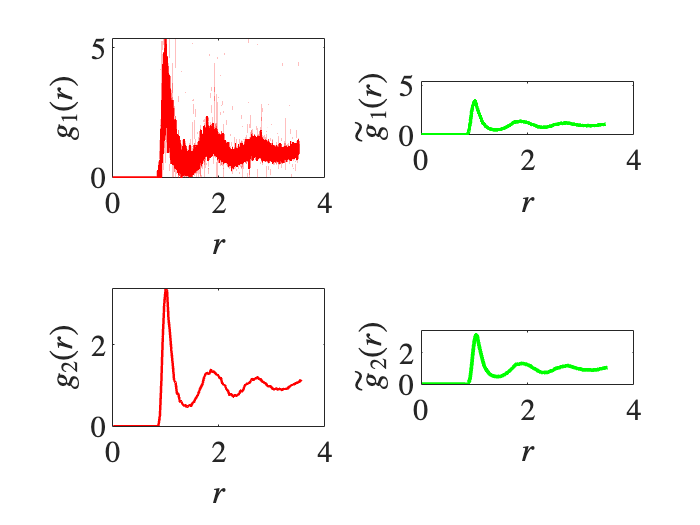

% plotting g(r) after use of KAMEL-LOBE
close all

for i=1:NumData
    subplot(NumData,2,2*i-1)
    pRaw = plot(RDF{i}(:,1),RDF{i}(:,2),'r','LineWidth',2);
    ylabel_name_1 = sprintf('$g_%d(r)$',i);
    xlabel('$r$','Interpreter','latex');
    ylabel(ylabel_name_1,'Interpreter','latex');
    set(gca,'FontSize', 24);
    set(gca,'fontname','times')
    ylim([0 max(RDF{i}(:,2))])
    
    subplot(NumData,2,2*i)
    m_KL = ceil(2*w/delr(i,1));
    p1 = plot(RDF{i}(1:end-m_KL,1),gr_convert{i}(1:end-m_KL,1)','g','LineWidth',3);
    xlabel('$r$','Interpreter','latex');
    ylabel_name_2 = sprintf('$\\tilde g_%d(r)$',i);
    ylabel(ylabel_name_2,'Interpreter','latex');
    set(gca,'FontSize', 24);
    set(gca,'fontname','times')
    ylim([0 max(RDF{i}(:,2))])
    pbaspect([4 1 1])
    
end

## Comparison

Here, we compare the difference and ratio between the raw RDFs (red lines below) against the difference between the RDFs processed using KAMEL-LOBE (green lines below). We see a difference closer to zero and a ratio closer to unity following the use of KAMEL-LOBE.

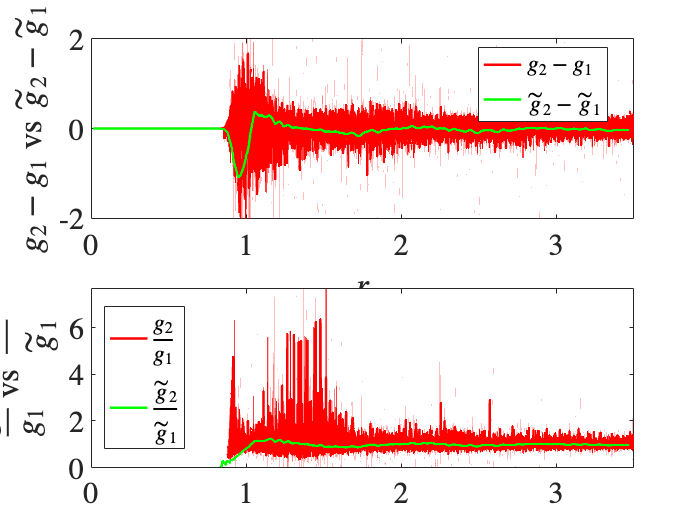

close all
[minDelr,imin] = min(delr); % Finding which RDF sample has a smaller \Delta r, i.e. more bins. The other RDF should be upsampled 
[maxDelr,imax] = max(delr); % The other RDF should be upsampled 

m_KL = ceil(2*w/delr(imin,1)); % Bin width for the first RDF

gr_upsample = interp1(RDF{imax}(:,1),RDF{imax}(:,2),RDF{imin}(:,1)); % upsampling RDF with less bins
Difference = gr_upsample - RDF{imin}(1:end,2);
Ratio = gr_upsample./RDF{imin}(1:end,2);

gr_convert_upsample = interp1(RDF{imax}(:,1),gr_convert{imax}(:,1),RDF{imin}(:,1));
Difference_convert = gr_convert_upsample - gr_convert{imin}(:,1);
Ratio_convert = gr_convert_upsample./gr_convert{imin}(:,1);

close all

subplot(2,2,[1,2])
pRaw = plot(RDF{imin}(1:end,1),Difference,'r','LineWidth',2);
hold on
pConvert = plot(RDF{imin}(1:end-m_KL,1),Difference_convert(1:end-m_KL,1),'g','LineWidth',2);

xlabel('$r$','Interpreter','latex');
ylabel('$g_2-g_1 \; \mathrm{vs} \; \tilde g_2 - \tilde g_1  $','Interpreter','latex');
set(gca,'FontSize', 24);
set(gca,'fontname','times')
[~, objh] = legend({'$g_2-g_1$','$\tilde g_2-\tilde g_1$'},'Interpreter','latex','location', 'Best', 'Fontsize', 18);
xlim([0 3.5])

subplot(2,2,[3,4])
pRaw = plot(RDF{imin}(1:end,1),Ratio,'r','LineWidth',2);
hold on
pConvert = plot(RDF{imin}(1:end-m_KL,1),Ratio_convert(1:end-m_KL,1),'g','LineWidth',2);
xlabel('$r$','Interpreter','latex');
ylabel('$\frac{g_2}{g_1} \; \mathrm{vs} \; \frac{\tilde g_2}{\tilde g_1}  $','Interpreter','latex');
set(gca,'FontSize', 24);
set(gca,'fontname','times')
[~, objh] = legend({'$\frac{g_2}{g_1}$','$\frac{\tilde g_2}{\tilde g_1}$'},'Interpreter','latex','location', 'Best', 'Fontsize', 18);
xlim([0 3.5])